During a crime scene investigation the surface temperature of a corpse is measured to be 30 °C when it was first discovered. One hour later it is measured as 26 °C. Use Newton’s law of cooling to determine the time of death if the ambient temperature is 20 °C and the temperature when the person was alive is assumed about 37 °C. We also assume that the ambient temperature has remain approximately constant (because the AC in the room was on). Click here to get a Matlab code and some hints on how to solve it. 

Newton's law of cooling states that

 
$$\frac{dT}{dt}=-k(T-T_0)$$


In this case the ONLY knowns that "fit" into the equation above are the ambient temperature and initial temperaure of the person when alive. 

The good news; the code below solves the equation above. But we do not know "k" right? Well, we come up with several guesses **and the one that "fits" the closest to our data** (when body discovered temperature was 30° and an hour later 26°) is the one we can use to find when the murder took place!

clear all
k=0.54;% wild guess
Ta=20;
IC=37;
tspan=[0 10];
f= @(t,x) (-k*(x(1)-Ta)); %define cooling law as a function. t is time and x is the temperature
[t,x]=ode45(f,tspan,IC)

t =          0
    0.2025
    0.4050
    0.6074
    0.8099
    1.0599
    1.3099
    1.5599
    1.8099
    2.0599


x =    37.0000
   35.2391
   33.6606
   32.2458
   30.9776
   29.5910
   28.3796
   27.3216
   26.3973
   25.5892


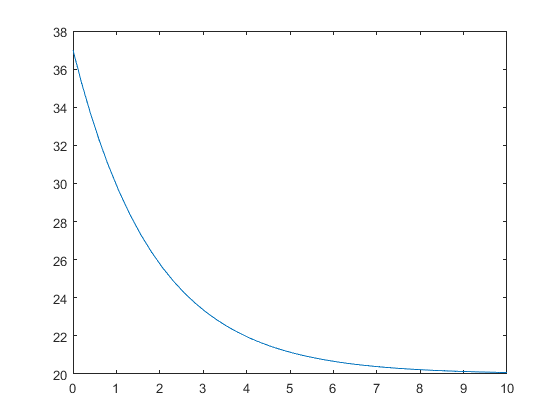

plot(t,x)


%does it look like this k is appropriate? Think: how much time elapses between 30°
%and 26°? If not an hour then play around with "k" to find a better fit.
%try k=0.6
%all this can be of course automated with a simple for loop and an "if"
%statement